## Alternating Directions Implicit method

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

f = @(t,P,Z) a*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*Z;

prey = 40; predator = 20; Nx = 100; Ny = 100;
P0 = prey * (1 + 0.5*rand(Nx,Ny));
Z0 = predator * (1 + 0.5*rand(Nx,Ny));
Dp = 1e-5; Dz = 1e-5;
n = 1000; t_end = 24;

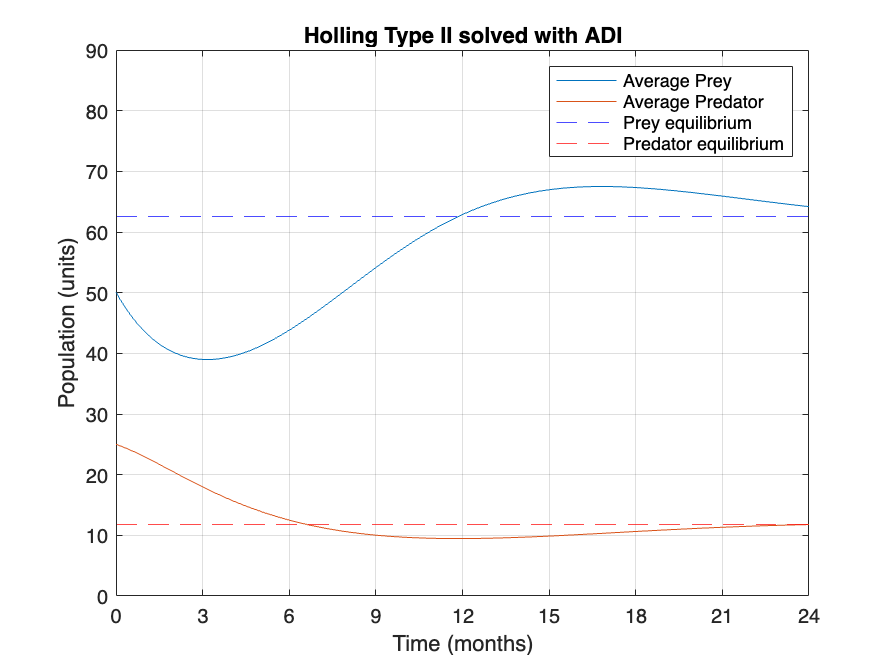

[t,P,Z] = ADIDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II solved with ADI")

xlim([0 t_end])
ylim([0 90])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Holling Type II spacetime representation (horizontal slices)')

Holling Type II spacetime representation (horizontal slices)


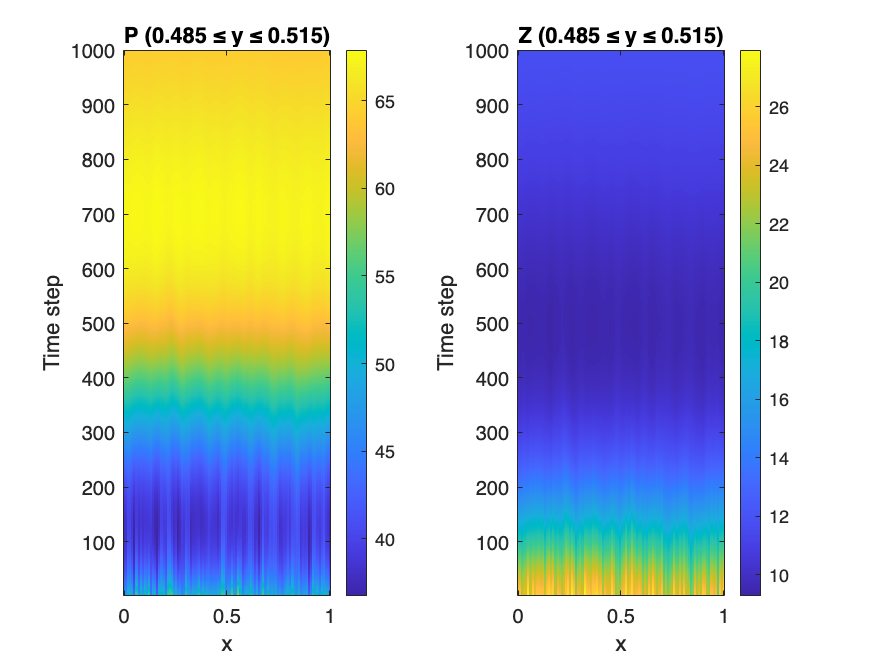

SpacetimeBand(P, Z, 0.5, 0.05)

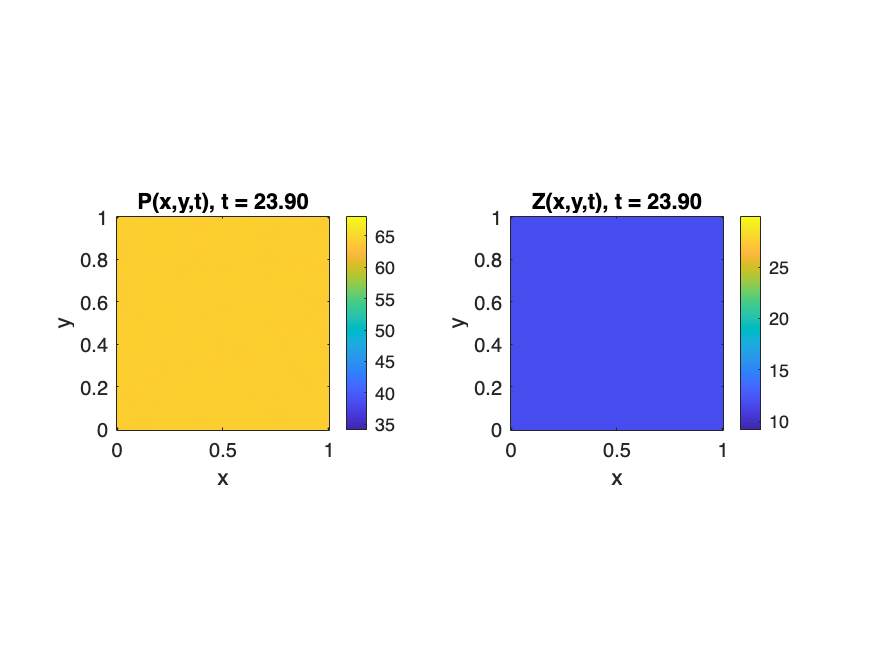


DiffusionPlot(t,P,Z)

## Non autonomous model

A = 0.75;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey
alpha = 0.5;
phi = 3;

f = @(t,P,Z) A*(1/2+cos(pi*t/12).^2)*P.*(1-P/K)-b*P.*Z./(1+b*h*P);
g = @(t,P,Z) c*b*P.*Z./(1+b*h*P) - d*(1+alpha*cos(pi*(t+phi)/6))*Z;

Dp = 1e-5; Dz = 1e-4;
n = 100; t_end = 48;

prey = 40; predator = 20; Nx = 100; Ny = 100;

x = linspace(0,1,Nx);
y = linspace(0,1,Ny);
[X,Y] = meshgrid(y,x);
A = 0.8;
sigma = 0.08;

P0 = prey*ones(Nx,Ny);
Z0 = predator + A*predator*exp(-((X-0.5).^2 + (Y-0.5).^2)/(2*sigma^2));

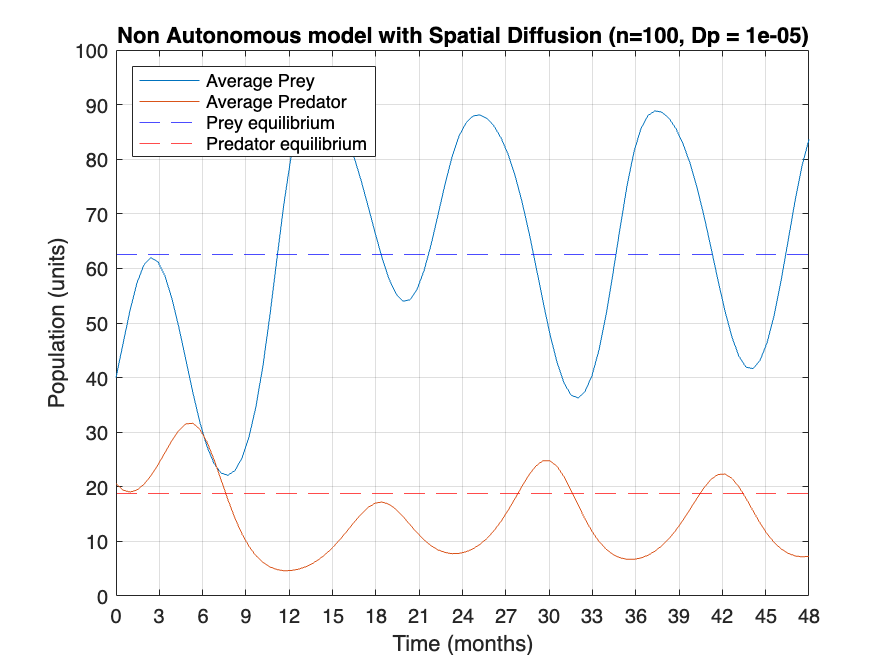

[t,P,Z] = ADIDiffusion(f,g, P0, Z0, Dp, Dz, t_end, n);

% Average population plot
figure()
plot(t,squeeze(mean(P, [1 2])))
hold on
plot(t,squeeze(mean(Z, [1 2])))
hold off
grid

pred_eq = -A*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Average Prey","Average Predator","Prey equilibrium","Predator equilibrium",location="northwest")
title("Non Autonomous model with Spatial Diffusion (n=" + n +", Dp = "+ Dp +")")

xlim([0 t_end])
ylim([0 100])
xticks(0:3:t_end)
ylabel("Population (units)")
xlabel("Time (months)")


disp('Non Autonomous model spacetime representation (horizontal slices)')

Non Autonomous model spacetime representation (horizontal slices)


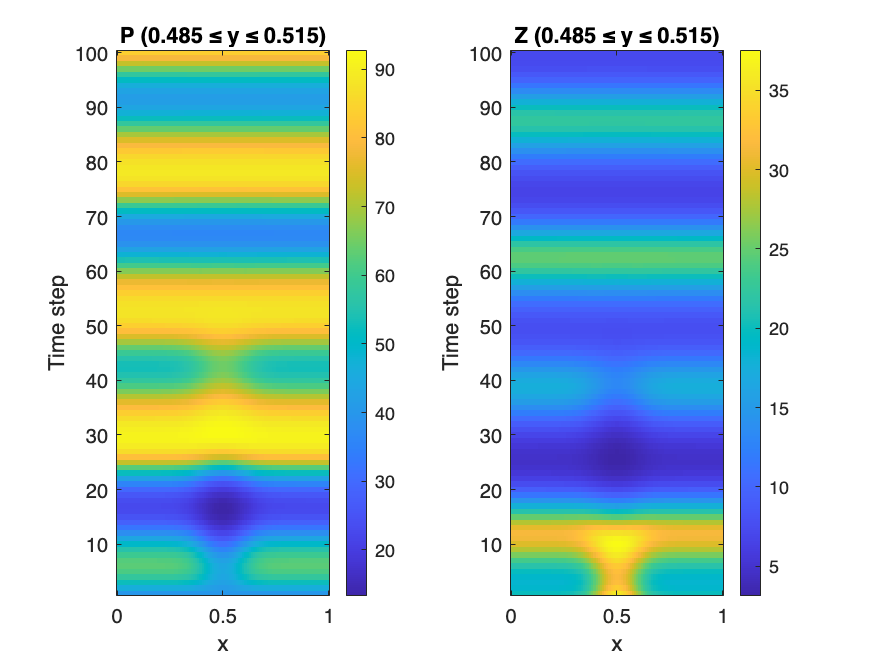

SpacetimeBand(P, Z, 0.5, 0.05)